# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 7-a. 이산 시간 개루프 시스템의 안정성 해석**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 극점 위치에 따른 시스템의 안정성(stability) 해석

다음의 두 연속 시간 시스템을 생각해봅시다. 


$$G_1(s) = \frac{1}{s^2 + 3s + 2} = \frac{1}{(s+1)(s+2)},\quad\quad G_2(s) = \frac{1}{s^2 + s -2} = \frac{1}{(s+2)(s-1)}$$


G1_tf = tf(1,[1 3 2]);
G2_tf = tf(1,[1 1 -2]);

3학년 2학기 제어공학 교과목에 따르면, 각각의 시스템의 안정도(stability)는 다음과 같이 판별됩니다.

- $G_1(s)$ : 모든 극점들이 복소 평면 상에서 왼쪽에 위치하므로, 안정(stable)합니다.

- $G_2(s)$ : 일부 극점들이 복소 평면 상에서 오른쪽에 위치하므로, 불안정(unstable)합니다.

 위의 두 연속 시간 시스템들의 펄스 전달함수는 다음과 같이 얻습니다.

T = 0.2;
Gd1_tf = c2d(G1_tf, T, 'zoh');
Gd2_tf = c2d(G2_tf, T, 'zoh');

이산 시간 시스템들의 극점들은 각각 아래와 같습니다. 

pole(Gd1_tf)

ans =     0.8187
    0.6703


pole(Gd2_tf)

ans =     1.2214
    0.6703


이 극점의 위치를 통해, 두 이산 시간 시스템의 안정성을 다음과 같이 판단할 수 있습니다.

- $G_1^d(z)$ : 두 극점 모두 단위원(unit circle) 안에 위치하므로, 안정합니다.

- $G_2^d(z)$ : 일부 극점이 단위원(unit circle) 밖에 위치하므로, 불안정합니다.

사실 이산 시간 시스템의 극점들은 연속 시간 시스템의 극점과 밀접한 연관이 있습니다. 

예를 들어 $G_1(s)$는 $s=-1$, $s=-2$에 극점을 가지는데, 이에 대응되는 이산 시간 시스템 $G^d_1(z)$의 극점들은 $z=e^{-T}$, $z=e^{-2T}$로 계산됩니다. 

한편 위의 시스템들의 안정성은 시간 영역에서도 쉽게 확인할 수 있습니다. 두 개루프 시스템에 대한 단위 계단 응답을 그리면 다음과 같습니다.

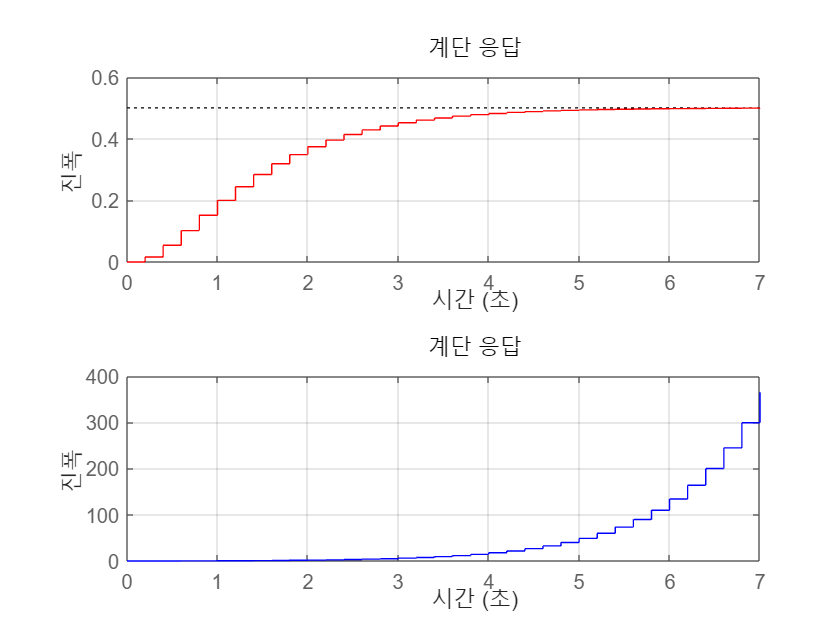

figure();
subplot(2,1,1);
    step(Gd1_tf, 'r'); xlim([0 7]); grid on;
subplot(2,1,2)
    step(Gd2_tf, 'b'); xlim([0 7]); grid on;

### Topic 2 : 상태 변수 모델에서의 안정성 해석

개루프 시스템을 표현하는 상태 변수 모델로부터 시스템의 안정성을 판별할 수도 있습니다. 

이를 위해 `ss` 함수를 이용하여 $G_1^d(z)$를 전달함수로 가지는 이산 시간 시스템의 상태 변수 모델을 다음과 같이 얻을 수 있습니다.

Gd1_ss = ss(Gd1_tf)

Gd_ss_1 =
 
  A = 
            x1       x2
   x1    1.489  -0.5488
   x2        1        0
 
  B = 
          u1
   x1  0.125
   x2      0
 
  C = 
           x1      x2
   y1  0.1314  0.1076
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.


이제 `eig` 함수를 이용하여, 위의 상태 변수 모델에서 A 행렬의 고유값(eigenvalue)를 계산해보면 다음과 같습니다.

eig(Gd1_ss.A)

ans =     0.8187
    0.6703


위의 고유값들은 사실 전달함수인 `Gd1_tf` 의 극점과 동일함에 주목합시다.

### Topic 3 : 쌍선형 변환을 이용한 안정성 판별

한편 이산 시간 시스템의 안정성은 쌍선형 변환(bilinear transformation)을 통해 연속 시간 시스템으로 변환하여 해석할 수도 있습니다. 

위의 이산 시간 시스템 $G_1^d(z)$는 쌍선형 변환의 정의식


$$G_1^{\rm w}({\rm w})=G_1^d(z)\bigg|_{{\rm w}=\frac{2(z-1)}{T(z+1)}}$$


을 통해 변환할 수 있습니다. 하지만 MATLAB에서는 `d2c` 함수를 이용하여 간편하게 계산할 수 있습니다.

Gw1_tf = d2c(Gd1_tf, 'tustin')

Gw_tf_1 =
 
  -0.0009803 s^2 - 0.08856 s + 0.9836
  -----------------------------------
         s^2 + 2.97 s + 1.967
 
연속시간 전달 함수입니다.
모델 속성


이렇게 변환된 $G_1^{\rm w}({\rm w})$의 극점은 아래와 같이 계산됩니다.

pole(Gw1_tf)

ans =    -1.9738
   -0.9967


이 극점들은 연속 시간의 안정 영역(stable region)인 좌반평면(left-half plane)에 위치해있으며, 쌍선형 변환의 특징에 의해 기존 이산 시간 시스템 $G_1^d(z)$ 역시 안정하다고 결론지을 수 있습니다. 

유의할 점은, 변환된 전달함수인 $G_1^{\rm w}({\rm w})$의 극점은 이산화하기 전의 연속 시간 전달함수 $G_1(s)$의 극점과 정확히 같지는 않다는 점입니다.

pole(G1_tf)

ans =     -2
    -1


### Topic 4 : 전달함수의 극점과 상태 변수 모델의 A 행렬 고유값과의 관계

Topic 2의 예시에서 어떤 시스템의 전달함수 극점이 상태 변수 모델의 A 행렬 고유값과 같았음을 확인하였습니다.

하지만 이러한 등가성은 항상 만족되지 않습니다. 좀 더 자세히 말하자면,

- **전달함수의 극점은 항상 상태 변수 모델의 A 행렬 고유값 중 하나입니다.**

- 하지만 **상태 변수 모델의 A 행렬 고유값은 전달함수의 극점이 아닐 수 있습니다.**

2번째 문장이 참임을 검증하기 위해, 다음의 두 이산 시간 시스템을 생각해봅시다.


$$G_1^d(z)=\frac{1}{z-1.5},\quad G_2^d(z) = \frac{2z-3}{z-0.5}$$


num_Gd1_tf = 1;
den_Gd1_tf = [1 -1.5];
Gd1_tf = tf(num_Gd1_tf, den_Gd1_tf, T);

num_Gd2_tf = [2 -3];
den_Gd2_tf = [1 -0.5];
Gd2_tf = tf(num_Gd2_tf, den_Gd2_tf, T);

극점의 위치를 고려해볼 때, 첫 번째 시스템은 안정하고 두 번째 시스템은 불안정합니다. 또한 첫 번째 시스템의 극점이 두 번째 시스템의 영점과 일치합니다. 

이제 이 두 시스템을 직렬로 연결한 시스템의 전달함수


$$G^d(z)=G_2^d(z)G_1^d(z) = \frac{2}{z-0.5}$$


를 생각해봅시다. 두 시스템의 위치가 동일한 극점과 영점이 상쇄되고, 결과적으로 직렬 연결된 시스템의 전달함수의 극점은 아래와 같이 하나만 남게 됩니다.

Gd_tf = Gd2_tf * Gd1_tf;
Gd_tf = minreal(Gd_tf)

Gd_tf =
 
     2
  -------
  z - 0.5
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


pole(Gd_tf)

ans = 0.5000

한편 동일한 직렬 연결된 시스템의 상태 변수 모델을 아래와 같이 계산해보면, A 행렬의 고유값이 2개임을 쉽게 확인할 수 있습니다. 

Gd1_ss = ss(Gd1_tf);
Gd2_ss = ss(Gd2_tf);

Gd_ss = Gd2_ss*Gd1_ss

Gd_ss =
 
  A = 
        x1   x2
   x1  0.5    2
   x2    0  1.5
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1  -1   2
 
  D = 
       u1
   y1   0
 
샘플 시간: 0.2 seconds
이산시간 상태공간 모델입니다.
모델 속성


eig(Gd_ss.A)

ans =     0.5000
    1.5000


여기서 $z=0.5$에 위치한 고유값은 실제로 전달함수의 극점입니다. 

한편 $z=1.5$는 $G_1^d(z)$와 $G_2^d(z)$를 곱하는 과정에서 상쇄된 전달함수의 극점입니다.

실제로 이 상태 변수 모델에 대한 전달함수를 `tf` 함수를 이용하여 구하면 앞서 계산한 전달함수와 동일함을 보일 수 있습니다.

tf(Gd_ss);
minreal(tf(Gd_ss))

ans =
 
     2
  -------
  z - 0.5
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


그래서 이 시스템은 안정할까요? 아니면 불안정할까요? 정답은, "안정하기도 하고, 불안정하기도 하다"입니다. 

- **단순히 이 시스템의 입/출력 관계만 생각해보면, 이 시스템은 안정합니다. 즉, 유한한 크기의 신호를 입력으로 넣으면, 그에 해당하는 출력도 항상 유한합니다. **

- **하지만 이 시스템의 내부를 살펴보면, 내부의 신호 중 안정화되지 못하고 발산하는 신호가 존재하게 됩니다. 따라서 내부적으로는 불안정하다고 할 수 있습니다. **

위의 메세지를 Simulink 모의실험을 통해 1번 더 확인해봅시다.

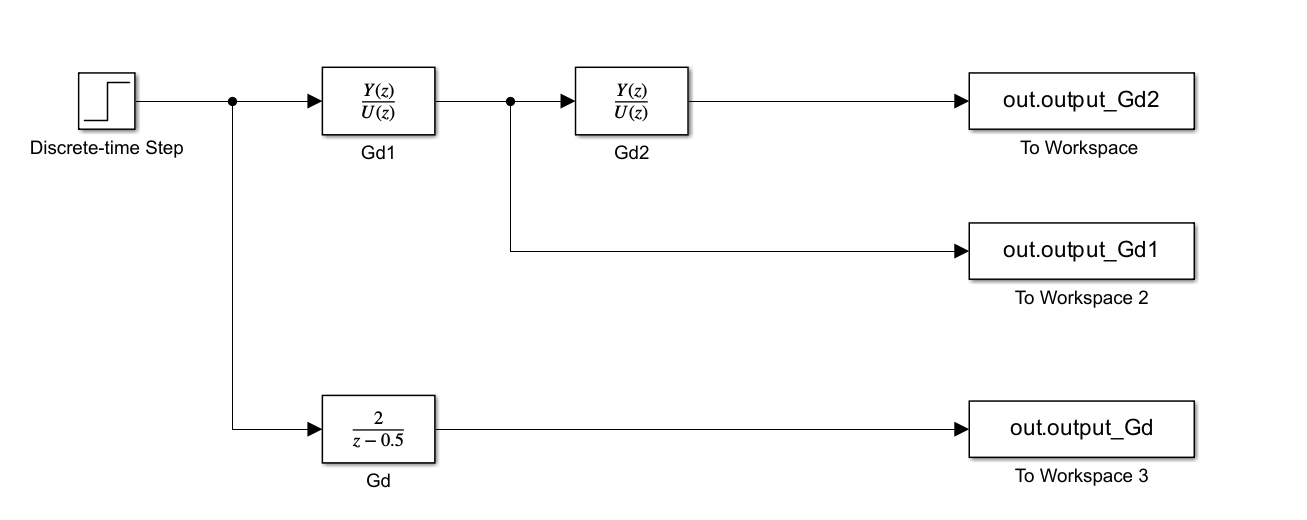

T_sim = 3;
dt_sim = 0.001;             

sim('sim_topic4.slx');

시스템 또는 파일 'sim_topic4.slx'을(를) 찾을 수 없습니다.

simout = ans;
time_dt_sim4 = simout.time_dt;
output_Gd_sim4 = simout.output_Gd;
output_Gd1_sim4 = simout.output_Gd1;
output_Gd2_sim4 = simout.output_Gd2;

f = figure();
f.Position = [100 100 500 500];
subplot(3,1,1)
    stem(time_dt_sim4,output_Gd_sim4,'--b','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output of $G^d(z)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([0 10]);
subplot(3,1,2)
    stem(time_dt_sim4,output_Gd2_sim4,'k','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output of $G^d_2(z)G^d_1(z)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([0 10]);
subplot(3,1,3)
    stem(time_dt_sim4,output_Gd1_sim4,'--r','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output of $G^d_1(z)$','Interpreter','latex');
    xlim([0 T_sim]); 
    ylim([0 100]);    